clear all; clc; close all;

% Model of auditory primary cortex A1, following
% Loebel et al.(2007)
% https://doi.org/10.3389/neuro.01.1.1.015.2007

## 1. Parameters

columns = 15;
cells_per_column = 200;
N_E = 100;
N_I = cells_per_column - N_E;

Tau_E = 0.001; % [s]
Tau_I = 0.001; % [s]

Tau_ref_E = 3*10^(-3); % [s]
Tau_ref_I = 3*10^(-3); % [s]

J_EE = [0.015,0.045,6,0.045,0.015]; % index goes from -2 to 2
J_IE = [0.0015,0.0035,0.5,0.0035,0.0015];
J_EI = -4; 
J_II = -0.5;

% synaptic resources
U = 0.5;
Tau_rec = 0.8; % [s]

% background activity
e_max = 10; % [Hz]
e_min = -10; % [Hz]

% stimulus
alpha = 2;
lambda_c = 0.25;
delta_left = 5;
delta_right= 5;

## 1.1. Compress all parameters into a couple of variables

params.N_E = N_E;
params.N_I = N_I;
params.columns = columns;
params.Tau_E = Tau_E;
params.Tau_I = Tau_I;
params.Taur_ref_E = Tau_ref_E;
params.Taur_ref_I = Tau_ref_I;
params.J_EE = J_EE;
params.J_EI = J_EI;
params.J_IE = J_IE;
params.J_II = J_II;
params.U = U;
params.Tau_rec = Tau_rec;

s_params.alpha = alpha;
s_params.lambda_c = lambda_c;
s_params.delta_left = delta_left;
s_params.delta_right= delta_right;

## 1.2. External input

Create background noise

e_E = zeros(N_E,columns); % [Hz]
e_I = zeros(N_I,columns); % [Hz]

rng('default');
for ii = 1:columns
    init_e_E = rand(N_E,1); %between (0,1)
    init_e_I = rand(N_I,1);
    % scale
    highest_eE = max(init_e_E);
    lowest_eE = min(init_e_E);
    highest_eI = max(init_e_I);
    lowest_eI = min(init_e_I);
    e_E_range = max(init_e_E) - min(init_e_E);
    e_I_range = max(init_e_I) - min(init_e_I);
    
    actual_eE = (1/e_E_range)*(init_e_E*(e_max-e_min)+(e_min*highest_eE-e_max*lowest_eE));
    actual_eI = (1/e_I_range)*(init_e_I*(e_max-e_min)+(e_min*highest_eI-e_max*lowest_eI));

    e_E(:,ii) = sort(actual_eE);
    e_I(:,ii) = sort(actual_eI);
end

## Figure 2

%{
figure();
start_time = 0.1; % s 
stimuli_durations = [0.4]; % how long each stimulus lasts
s = zeros(max(size(stimuli_durations)),columns);
s(1,:) = [0,0,0,0,0,0,0,4,0,0,0,0,0,0,0];
s = s_tuning_curve(s,s_params);

[t,E,I,x,y] = solve_complex_stimuli(start_time,stimuli_durations,s,params,e_E,e_I);
% plot average activity per column
E_col_avg = mean(E,3);

%t = 1000*(t-start_time); % scale to milliseconds, and offset so that the first stimulus is at t=0
max_amplitude = max(E_col_avg,[],'all');
for col =6:10
    subplot(3,5,col-5);
    plot(t,E_col_avg(:,col),'DisplayName',sprintf('col %d',col));
    ylim([0,max_amplitude]);
    
    subplot(3,5,col);
    plot(t,s(col)*heaviside(t)); % The temporal envelope zeta used, is the heaviside function
    ylim([0,max(s)+1]);
    
end
subplot(3,5,[11,12,13,14,15]);
plot(6:10,s(6:10));
xticks([6,7,8,9,10]);


## Figure 3

figure();
start_time = 0.025; % s
stimuli_durations = [0.075]; % how long each stimulus lasts
s = zeros(max(size(stimuli_durations)),columns);
min_input = 2; max_input = 8;

for ii = min_input:max_input % arbitrary increasing stimulus
    
    s(1,:) = [0,0,0,0,0,0,0,ii,0,0,0,0,0,0,0];
    s = s_tuning_curve(s,s_params);
    [t,E,I,x,y] = solve_complex_stimuli(start_time,stimuli_durations,s,params,e_E,e_I); % average activity per column
    E_col_avg = mean(E,3);
    x_axis = 1:size(E_col_avg,2)+1; %columns (+1 so that the last column appears interpolated from last_column to last_column+1)
    y_axis = t;
    [X_axis,Y_axis] = meshgrid(x_axis,y_axis);
    subplot(max_input+1,1,max_input-ii+1);
    grid off;
    surf(X_axis-0.5,Y_axis,cat(2,E_col_avg,zeros(size(t,1),1)),'edgecolor','none');
    xlim([0.5,15.5]);
    ylim([0,start_time+stimuli_durations(1)]);
    xticks([]);
    colorbar;
    colormap('jet')
    view(2);
    subplot(max_input+1,1,max_input+1);
    plot(1:columns,s);
    xlim([0.5,15.5]);
    xticks([1:columns]);
    hold on;
end
%}

## Figure 7 (Issy Code)

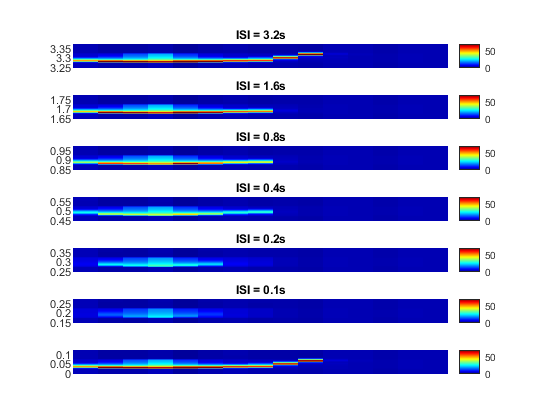

figure();
start_time = 0.025; % seconds to wait before first stimulus
time_at_end = 0.05; % seconds to wait after last stimulus

interstimulus_intervals = Tau_rec.*[1/8, 1/4, 1/2, 1, 2, 4]; % the sequence of interstimulus intervals to try

for i = 1:length(interstimulus_intervals)
    
    isi = interstimulus_intervals(i);
    stimuli_durations = [0.05, isi, 0.05, time_at_end]; % how long each stimulus lasts (i.e. there are 4 phases of stimulus). Each tone is provided for 0.05 seconds as per the caption in Figure 6A ("50 ms duration, amplitude of 10.."). The time between the tones is the ISI (interstimulus interval). At the end have a bit of time to see how the second tone affects activity.
    s = zeros(max(size(stimuli_durations)),columns); % empty stimulus matrix
    s(1,:) = [0,0,0,10,0,0,0,0,0,0,0,0,0,0,0]; % first phase is tone of amplitude 10 at the 4th column, 0 everywhere else (First tone, "Mask")
    s(2,:) = [0,0,0,0,0,0,0,0,0,0,0,0,0,0,0]; % second phase is 0 everywhere (Interstimulus Interval)
    s(3,:) = [0,0,0,10,0,0,0,0,0,0,0,0,0,0,0]; % third phase is tone of amplitude 10 at the 4th column, 0 everywhere else (Second tone, "Probe")
    s(4,:) = [0,0,0,0,0,0,0,0,0,0,0,0,0,0,0]; % fourth phase is 0 everywhere

    s = s_tuning_curve(s,s_params); % spread the pure tone across all the columns exponentially
 
    [t,E,I,x,y] = solve_complex_stimuli(start_time,stimuli_durations,s,params,e_E,e_I); % Run the ODE
    E_col_avg = mean(E,3); % average activity per column
    x_axis = 1:size(E_col_avg,2)+1; %columns (+1 so that the last column appears interpolated from last_column to last_column+1)
    y_axis = t;
    [X_axis,Y_axis] = meshgrid(x_axis,y_axis); % distribute the results evenly
    subplot(7,1,7-i); % fill in the (7-i)-th row of the subplot
    grid off;
    surf(X_axis-0.5,Y_axis,cat(2,E_col_avg,zeros(size(t,1),1)),'edgecolor','none'); % draw the surface (i.e. colour) over
    xlim([0.5,15.5]); 
    ylim([stimuli_durations(1) + stimuli_durations(2),start_time+sum(stimuli_durations)]); % only show the results in the last two periods (i.e. after the ISI)
    xticks([]);
    colorbar;
    caxis([0 70]) % max colour scaled to 70Hz as in paper
    colormap('jet')
    title(['ISI = ', num2str(isi), 's'])
    view(2); % show the color map in 2 dimensions
    %subplot(max_input+1,1,max_input+1);
    %plot(1:columns,s);
    %xlim([0.5,15.5]);
    %xticks([1:columns]);
    hold on;
end

subplot(7,1,7); % plot the initial tone response at the very bottom
grid off;
surf(X_axis-0.5,Y_axis,cat(2,E_col_avg,zeros(size(t,1),1)),'edgecolor','none'); 
xlim([0.5,15.5]);
ylim([0,start_time+stimuli_durations(1)+time_at_end]); % only show from the start to after the first tone to show how the A1 responds to the initial tone
xticks([]);
colorbar;
caxis([0 70])
colormap('jet')
view(2);

## Figure 4

%{
figure(); start_time = 0; % s stimuli_durations = [0.075]; % how long each stimulus lasts
max_amp = 10; step = 1;

for tone_freq = 8:2:12
       t_peak_vec = zeros(1,1/step*max_amp);
       cont = 1;
       for tone_amp = 1:step:max_amp
           s = zeros(max(size(stimuli_durations)),columns);
           s(1,tone_freq) = tone_amp;
           s = s_tuning_curve(s,s_params);
           [t,E,I,x,y] = solve_complex_stimuli(start_time,stimuli_durations,s,params,e_E,e_I); % average activity per column E_col_avg = mean(E,3); I_col_avg = mean(I,3);
           E_col8 = E_col_avg(:,8);
           I_col8 = E_col_avg(:,8);
           [~,E_indices]=findpeaks(E_col8,'MinPeakHeight', 15); %Completely arbitrary threshold O_O
           [~,I_indices]=findpeaks(I_col8,'MinPeakHeight', 15);         
           time_E_peak = t(E_indices);
           time_I_peak = t(I_indices);
           if isempty(time_E_peak)
               t_peak_vec(cont) = nan;
           else
               t_peak_vec(cont) = time_E_peak;            
           end
           cont = cont+1;
       end
   hold on;
   plot(1:step:max_amp,1000*t_peak_vec,'.k');
end

ylim([0,40]); xlim([0,10]);
%}

## Functions

function [t_vec,E,I,x,y] = solve_complex_stimuli(start_time,dur_vec,s_matrix,params,e_E,e_I)
% Solve the auditory cortex system of ODEs for an arbitrary train of
% stimuli (s_matrix).
%
% s_matrix(onset_times, columns): Is a matrix with as many columns as
% auditory cortex columns, and as many rows as different stimulus onsets.
% dur_vec: vector of duration for each stimulus

## Create neurons

    E_ini = rand(params.N_E,params.columns);
    I_ini = rand(params.N_I,params.columns);

## Create synaptic resources

    x_ini = rand(size(E_ini));
    y_ini = rand(size(I_ini));

## Get initial conditions

set stimulus to 0 and let the system converge

    X0 = [E_ini(:); I_ini(:); x_ini(:); y_ini(:)];
    t_rest = 5*params.Tau_rec;
    [t, X] = ode45(@(t,X) dXdt(t,X,params,0,e_E,e_I),[0,t_rest],X0);

    [E,I,x,y] = reshape_X(X,[2,3,1], params);

    E0 = E(:,:,end);
    I0 = I(:,:,end);
    x0 = x(:,:,end);
    y0 = y(:,:,end);

## Solve ODE

    % if the starting time is different to 0, add a stimulus of 0 from t=0
    % to until the starting time
    dur_vec = dur_vec(:);
    if start_time ~= 0
        zero_stimulus = zeros(1,size(s_matrix,2));
        s_matrix = cat(1,zero_stimulus,s_matrix);
        dur_vec = cat(1,start_time,dur_vec);
    end
    
    time_sum = 0;
    E = [];
    I = [];
    x = [];
    y = [];
    t_vec = [];
    next_E0 = E0;
    next_I0 = I0;
    next_x0 = x0;
    next_y0 = y0;
    for jj = 1:size(dur_vec,1)
        t_span = [0, dur_vec(jj)];
        s = s_matrix(jj,:);
        X0 = [next_E0(:); next_I0(:); next_x0(:); next_y0(:)];
        [t, X] = ode45(@(t,X) dXdt(t,X,params,s,e_E,e_I),t_span,X0);

        t = t(:) + time_sum;
        time_sum = time_sum + dur_vec(jj);
        [E_jj,I_jj,x_jj,y_jj] = reshape_X(X,[1,3,2], params);% E(time,cols,N_E)
        
        E = cat(1,E,E_jj);
        I = cat(1,I,I_jj);
        x = cat(1,x,x_jj);
        y = cat(1,y,y_jj);
        t_vec = cat(1,t_vec,t);

        % the last E,I,x,y of each stimulus, are the initial conditions for
        % next one:
        [E0_jj,I0_jj,x0_jj,y0_jj] = reshape_X(X,[2,3,1], params);
        next_E0 = E0_jj(:,:,end);
        next_I0 = I0_jj(:,:,end);
        next_x0 = x0_jj(:,:,end);
        next_y0 = y0_jj(:,:,end);
           
    end
end
function dXdt = dXdt(t,X,params,s,e_E,e_I)
    [E,I,x,y] = reshape_X_single_time_point(X,params);
   
    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns;
    Tau_E = params.Tau_E;
    Tau_I = params.Tau_I;
    Tau_ref_E = params.Taur_ref_E;
    Tau_ref_I = params.Taur_ref_I;
    J_EE = params.J_EE;
    J_EI = params.J_EI;
    J_IE = params.J_IE;
    J_II = params.J_II;
    U = params.U;
    Tau_rec = params.Tau_rec;
    
    in_col_exci = sum(U*x.*E, 1);
    between_col_exci = zeros(5,columns);
    for R = -2:2 
        aux = circshift(in_col_exci,-R,2);
        if R<0
            aux(:,1:-R)=0;
        elseif R>0
            aux(:,end-(R-1):end)=0;
        end
        between_col_exci(R+3,:) = aux;
    end
    between_col_exci = (J_EE/N_E)*between_col_exci;
    in_col_inhi = (J_EI/N_I)*sum(U*y.*I, 1);
    relu = max((between_col_exci + in_col_inhi + e_E + s),0);

    dEdt= (1/Tau_E)*(-E + (1-Tau_ref_E*E).*relu);

## dIdt

    in_col_exci = sum(E, 1);
    between_col_exci = zeros(5,columns);
    for R = -2:2 
        aux = circshift(in_col_exci,-R,2);
        if R<0
            aux(:,1:-R)=0;
        elseif R>0
            aux(:,end-(R-1):end)=0;
        end
        between_col_exci(R+3,:) = aux;
    end
    between_col_exci = (J_IE/N_E)*between_col_exci;
    in_col_inhi = (J_II/N_I)*sum(I, 1);
    relu = max((between_col_exci + in_col_inhi + e_I),0);

    dIdt= (1/Tau_I)*(-I + (1-Tau_ref_I*I).*relu);

## dxdt

    dxdt = (1-x)/Tau_rec - U*x.*E;

## dydt

    dydt = (1-y)/Tau_rec - U*y.*I;


    dXdt = [dEdt(:); dIdt(:); dxdt(:); dydt(:)];
end

function [E,I,x,y] = reshape_X_single_time_point(X,params)
% Gets a vector X of size (4*cells_per_column*columns, 1) and returns
% 4 arrays: E, I, x, y; each of them of size (N_i, columns), where i 
% is either E for excitatory cells or I for inhibitory cells.

    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns; 
    % re-organize the vector X in its components
    cont = 1;
    E_col = X(1:N_E*columns);
    E = reshape(E_col,N_E,columns);
    cont = cont + size(E_col,1);
    
    I_col = X(cont:cont + N_I*columns-1);
    I = reshape(I_col,N_I,columns);
    cont = cont + size(I_col,1);
    
    x_col = X(cont:cont + N_E*columns-1);
    x = reshape(x_col,N_E,columns);
    cont = cont + size(x_col,1);

    y_col = X(cont: cont + N_I*columns-1);
    y = reshape(y_col,N_I,columns);
end

function [E,I,x,y] = reshape_X(X,order,params)
% Gets an array X of size (time_steps, 4*cells_per_column*columns) and returns
% 4 arrays: E, I, x, y; each of them of size (N_i, columns, time_steps), where i 
% is either E for excitatory cells or I for inhibitory cells.
% The order of the axes is given by the argument order:
% order = [2,3,1] -> (N_i, columns, time_steps). Useful when you need a
% 'photograph' of the variable at a single time_step.
%order = [1,3,2] -> (time_steps, columns, N_i. Useful for plotting the
%variable over time.

    N_E = params.N_E;
    N_I = params.N_I;
    columns = params.columns; 
    
    % Separate the vector X into E,I,x,y
    time_steps = size(X,1);
    cont = 1;
    
    E_col = X(:,cont:cont+N_E*columns-1);
    %E_col = X(1:time_steps*N_E*columns);
    cont = cont + size(E_col,2);
    I_col = X(:,cont:cont+N_I*columns-1);
    %I_col = X(1:time_steps*N_I*columns);
    cont = cont + size(I_col,2);
    x_col = X(:,cont:cont+N_E*columns-1);
    %x_col = X(1:time_steps*N_E*columns);
    cont = cont + size(x_col,2);
    y_col = X(:,cont:cont+N_I*columns-1);
    %y_col = X(1:time_steps*N_I*columns);

    % reshape each tensor in 3 dimensions, one for time, other for columns,
    % other for cells in the column
    E = reshape(E_col,time_steps,N_E,columns);
    I = reshape(I_col,time_steps,N_I,columns);
    x = reshape(x_col,time_steps,N_E,columns);
    y = reshape(y_col,time_steps,N_I,columns);

    % Re-organize the axes so that each tensor has the shape (cells_per_column,
    % columns, t)
    E = permute(E,order);
    I = permute(I,order);
    x = permute(x,order);
    y = permute(y,order);
end
function s = s_tuning_curve(s,s_params)
    columns = size(s,2);
    alpha = s_params.alpha;
    lambda_c = s_params.lambda_c;
    delta_left = s_params.delta_left;
    delta_right = s_params.delta_right;
    for tt = 1:size(s,1)
        A_vec = s(tt,:);      
        h = zeros(columns);
        for M = 1:size(s,2)
            for Q = 1:size(s,2)
                A = A_vec(M); 
                if Q > M
                    delta = delta_right;
                else
                    delta = delta_left;
                end
                lambda_s = ((A-alpha)/delta)*heaviside(A-alpha-eps) + lambda_c;
                h(M,Q) = A*exp(-abs(Q-M)/lambda_s);
            end
        end
        s(tt,:) = sum(h,1);
    end
end